%csvwrite('myFile.txt',[1 2 3 4 5 6 7 8 9;]);
dlmwrite('output.csv', ['q1','q2','q3''q4''q5'], '-append');

robo = loadrobot('abbIrb120');
ax = show(robo);

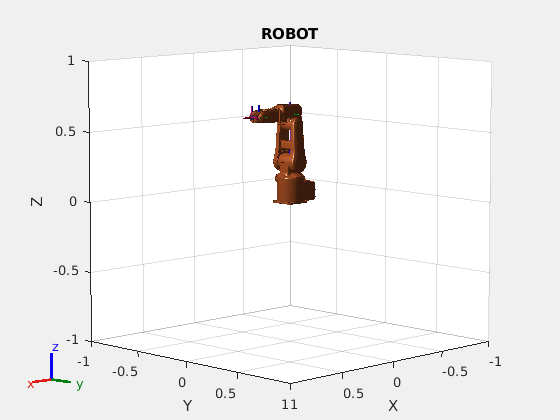

title(ax,'ROBOT');

pts = readtable('DataScience/project/archive/new_dataset.csv');
pts

pts = 15000×3 table
       x          y         z  
    _______    _______    _____

     0.2553       0.15    0.551
      0.492       -0.1    0.475
     0.2667      0.223    0.456
      0.485    -0.0314     0.62
      0.294     -0.229     0.51
      0.182    -0.0712    0.495
    0.35422    -0.0616     0.37
     0.2546      0.235    0.605
    0.34758      -0.15    0.459
     0.3948     -0.169    0.299
     0.3363      0.192    0.488
      0.248     0.0977    0.414
    0.35315     -0.142    0.632
      0.243      0.143    0.677
      0.223      0.153    0.536
     0.3233    -0.0989     0.59



x = pts(:,1);
y = pts(:,2);
z = pts(:,3);

x_d = table2array(x);
y_d = table2array(y);
z_d = table2array(z);

for i =1:15000
    pos = [x_d(i) y_d(i) z_d(i)];
    posvec = trvec2tform(pos);
    %disp('Position of tool: ');disp(posvec);
    
    ik = inverseKinematics("RigidBodyTree",robo);
    weights = [0 0 0 1 1 1];
    initialguess = homeConfiguration(robo);
    
    [configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);
    config = struct2table(configSoln);
    
    config = transpose(table2array(config(:,2)));
    %disp(config);
    %disp(pos);
    entry = [config pos];
    dlmwrite('output.csv',entry,'-append');
    %disp('Solution: ');disp(configSoln);
end
